clear all
addpath("functions/");


if isunix
  addpath("coppelia_files/linux")
elseif ismac
  addpath("coppelia_files/mac")
end


disp('Program started');

Program started


% sim=remApi('remoteApi','extApi.h'); % using the header (requires a compiler)
sim=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1); % just in case, close all opened connections
clientID=sim.simxStart('127.0.0.1',19997,true,true,5000,5);

if (clientID>-1)
    disp('Connected to remote API server');
    [returnCode]=sim.simxLoadScene(clientID,'scenes/1-dof scene.ttt',1,sim.simx_opmode_blocking)
    display(returnCode);
    
    % Now send some data to CoppeliaSim in a non-blocking fashion:
    sim.simxAddStatusbarMessage(clientID,'Hello CoppeliaSim!',sim.simx_opmode_oneshot);
    
    [returnCode,joint] = sim.simxGetObjectHandle(clientID,'Joint', sim.simx_opmode_blocking)
    
    %load Franka
    %[returnCode, baseHandle] = sim.simxLoadModel(clientID, 'models/robots/non-mobile/FrankaEmikaPanda.ttm', 0,sim.simx_opmode_blocking);
    %sim.simxAddStatusbarMessage(clientID,'Model loaded',sim.simx_opmode_oneshot);
    %display(returnCode);
    %display(baseHandle);
    
else
    disp('Failed connecting to remote API server');
end

Connected to remote API server


returnCode = 0

returnCode = 0

returnCode = 0

joint = int32
17

%[position, velocity, acceleration] = looping_splines([0 -10 -30 20 10 5 -10 0 60 40 50 20 30 0 45 70 20 -60 0 -50 -50 -100 -50 0]*pi/180, [0 1.5 2.7 4 5.5 7 8.5 11 14 16 17 18 19 20 22 23 25.5 28.5 30 32 34 36 38 40]);
%[position, velocity, acceleration] = looping_splines([0 -30 -10 -50 -70 -130 -50 -100 -30 0 30 10 50 70 130 50 100 30 0 -50 80 70 75 -50 0]*pi/180, [0 1.5 2.7 4 5.5 7 8.5 11 14 16 17 18 19 20 22 23 25.5 28.5 30 31 33 34 35 37 39]);

%[position, velocity, acceleration] = generate_exciting_traj();

load('data/1-dof/trajectory1/time.mat', 'time')
load('data/1-dof/trajectory1/pos.mat', 'position')
load('data/1-dof/trajectory1/vel.mat', 'velocity')
load("data/1-dof/trajectory1/acc.mat", 'acceleration')

[position, velocity, acceleration] = looping_splines(position, time);

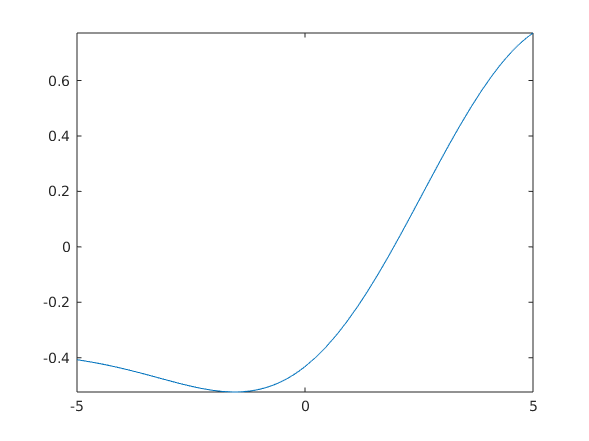

fplot(position)

## **Start Simulation**

sim.simxStartSimulation(clientID, sim.simx_opmode_oneshot);
[returnCode,joint_position]=sim.simxGetJointPosition(clientID,joint,sim.simx_opmode_streaming)

returnCode = 1

joint_position = single
43

controller_gain =460   

controller_gain = 460

Kp = 3*controller_gain;
Kd = 1.5*controller_gain;
Ki = 2*controller_gain;

measured_pos = zeros(1, 500000);
reference_pos = zeros(1, 500000);
measured_vel = zeros(1, 500000);
reference_vel = zeros(1, 500000);
time_axis = zeros(1, 500000);
error = zeros(1, 500000);
derror = zeros(1, 500000);
ierror = zeros(1, 500000);
torque = zeros(1, 500000);
computed = zeros(1, 500000);
correction = zeros(1, 500000);
i = 1;

queue = [0 0];

t0 = datetime('now');
t1 = t0;
start = t0;
integral = 0

integral = 0

while seconds(t1-start)<=30
    [returnCode,joint_position]=sim.simxGetJointPosition(clientID,joint,sim.simx_opmode_buffer);
    t1 = datetime('now');
    frame_period = (seconds(t1-start)/i);
    frame_rate = 1/frame_period;
    
    queue(2) = queue(1);
    queue(1) = joint_position;
    
    v = (queue(1)-queue(2))/seconds(t1-t0);
    measured_vel(i) = v;
    
    integral = integral + (position(seconds(t1-start)) - joint_position)*seconds(t1-t0);
    
    t0=t1;
    
    feedforward = 490.5*sin(position(seconds(t1-start))) + (134.7+25)*acceleration(seconds(t1-start));
    c = Kp*(position(seconds(t1-start)) - joint_position) + Kd*(velocity(seconds(t1-start)) - v) + Ki*integral;
    u = c + feedforward;
    torque(i) = double(u);
    computed(i) = feedforward;
    correction(i) = c;
    
    sim.simxSetJointTargetVelocity(clientID, joint, sign(u)*10e10, sim.simx_opmode_oneshot);
    sim.simxSetJointForce(clientID, joint, abs(u), sim.simx_opmode_oneshot);
    
    time_axis(i) = seconds(t1-start);
    
    measured_pos(i) = joint_position;
    reference_pos(i) = position(seconds(t1-start));
    
    reference_vel(i) = velocity(seconds(t1-start));
    
    error(i) = (position(seconds(t1-start)) - joint_position);
    derror(i) = velocity(seconds(t1-start)) - v;
    ierror(i) = integral;
    
    i = i+1;
    
    pause(0.05)
end

sim.simxStopSimulation(clientID, sim.simx_opmode_oneshot);

frame_rate

frame_rate = 18.6463

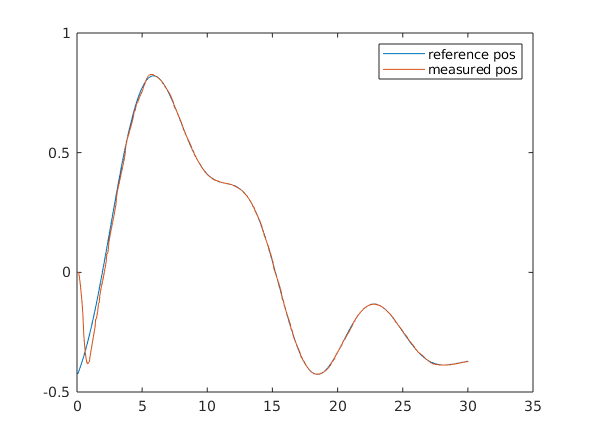

clf
plot(time_axis(1:i-1), reference_pos(1:i-1), time_axis(1:i-1), measured_pos(1:i-1));
legend ("reference pos", "measured pos")

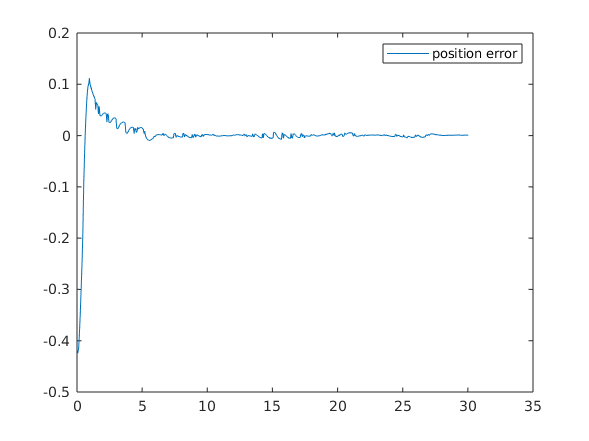

clf
plot(time_axis(1:i-1), error(1:i-1));
legend("position error")

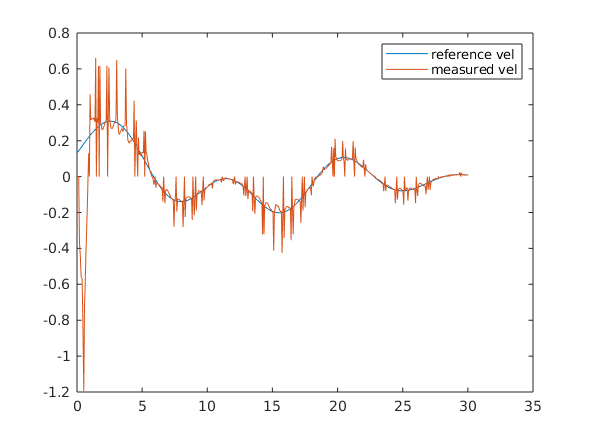

clf;
plot(time_axis(1:i-1), reference_vel(1:i-1), time_axis(1:i-1), measured_vel(1:i-1));
legend ("reference vel", "measured vel")

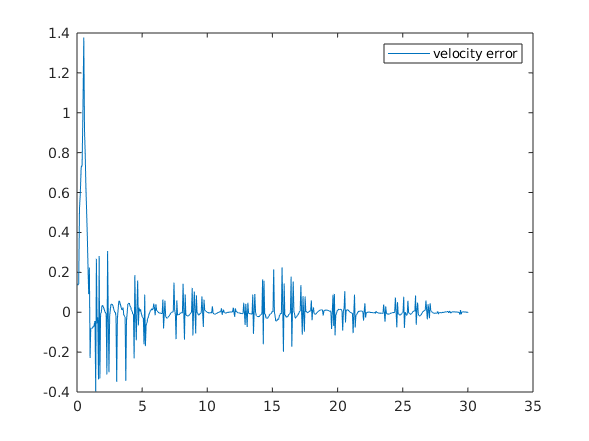

clf
plot(time_axis(1:i-1), derror(1:i-1));
legend("velocity error")

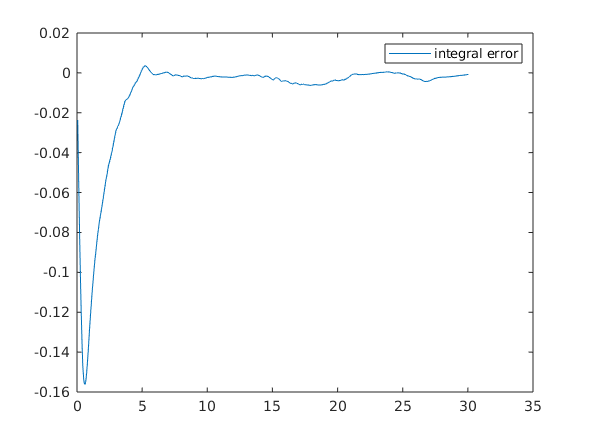

clf
plot(time_axis(1:i-1), ierror(1:i-1));
legend("integral error")

ORDER = 16;
FC_HIGH = frame_rate/16;  % Hz, used in low-pass and band-pass filters

filt = designfilt('lowpassiir', 'FilterOrder', ORDER, 'HalfPowerFrequency', FC_HIGH, 'SampleRate', frame_rate);

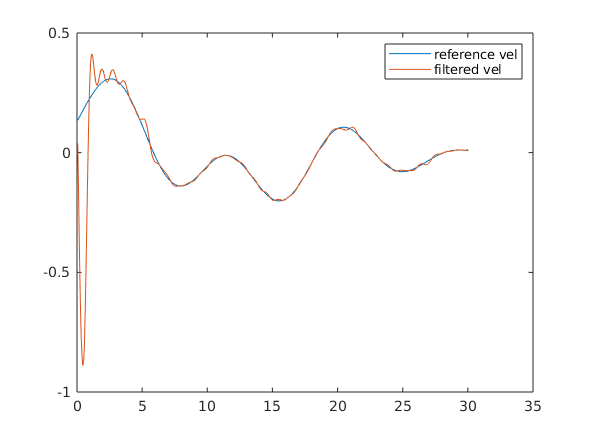

filtered_vel = filtfilt(filt, gradient(measured_pos(1:i-1),frame_period));
plot(time_axis(1:i-1), reference_vel(1:i-1), time_axis(1:i-1), filtered_vel(1:i-1));
legend ("reference vel", "filtered vel")

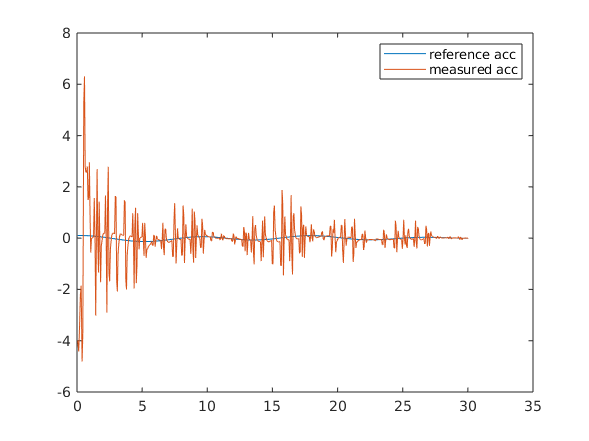

clf;
plot(time_axis(1:i-1), acceleration(time_axis(1:i-1)), time_axis(1:i-1), gradient(gradient(measured_pos(1:i-1), frame_period), frame_period));
legend ("reference acc", "measured acc")

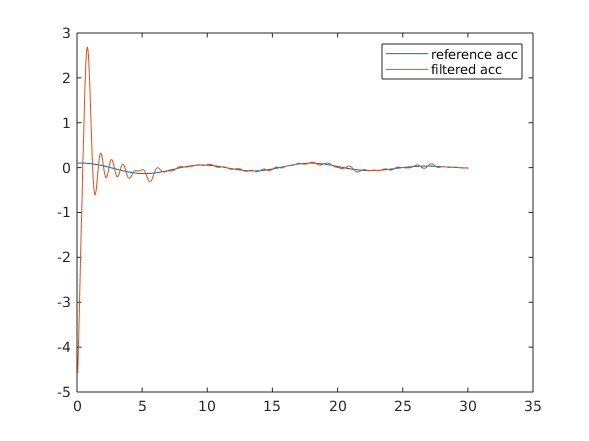

filtered_acc = filtfilt(filt,gradient(filtfilt(filt,gradient(measured_pos(1:i-1), frame_period)), frame_period));
plot(time_axis(1:i-1), acceleration(time_axis(1:i-1)), time_axis(1:i-1), filtered_acc(1:i-1));
legend ("reference acc", "filtered acc")

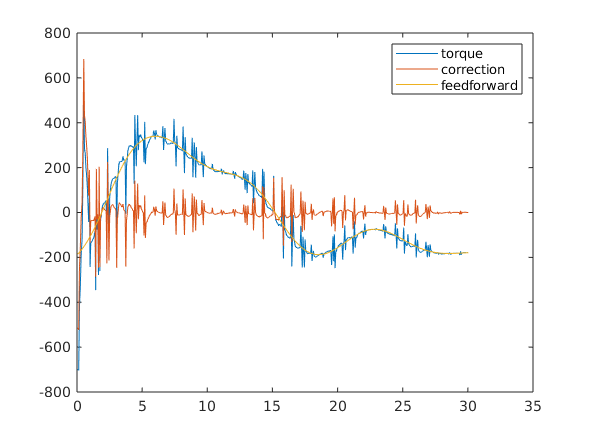

filtered_torque = filtfilt(filt, torque(1:i-1));
plot(time_axis(1:i-1), torque(1:i-1), time_axis(1:i-1), correction(1:i-1), time_axis(1:i-1), computed(1:i-1));
legend ("torque", "correction", "feedforward")

Y = zeros(i-1, 2);
u = zeros(i-1, 1);

Y(1:i-1, 1) = sin(measured_pos(1:i-1));
Y(1:i-1, 2) = filtered_acc(1:i-1);
u(1:i-1) = filtered_torque(1:i-1);

a = pinv(Y)*u

a =   486.8903
  124.7966


sum((Y*a-u).^2)

ans = 3.3223e+05



p = [200*rand(), 1*rand(), 1.347*2*rand()]; 

%algorithm

c = coefficients(p)

c =    74.0950
    1.2500


epsilon = 0

epsilon = 0

for i=1:1
    m = optimvar('m');
    d = optimvar('d');
    I = optimvar('I');
    prob = optimproblem;
    prob.Objective = sum((Y*coefficients([m, d, I])-u).^2);
    prob.Constraints.cons1 = m <= 200;
    prob.Constraints.cons2 = m >= 0;
    prob.Constraints.cons3 = d >= 0;
    prob.Constraints.cons4 = d <= 1;
    prob.Constraints.cons5 = I >= 0;
    prob.Constraints.cons6 = I <= 1.347*200;
    x0.m = p(1);
    x0.d = p(2);
    x0.I = p(3);
    sol = solve(prob, x0)
end


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    I: 110.9436
    d: 0.2791
    m: 177.8198


coefficients([sol.m, sol.d, sol.I])

ans =   486.8903
  124.7966


% Before closing the connection to CoppeliaSim, make sure that the last command sent out had time to arrive. You can guarantee this with (for example):
sim.simxGetPingTime(clientID);

% Now close the connection to CoppeliaSim:
sim.simxFinish(clientID);

sim.delete(); % call the destructor!

disp('Program ended');

Program ended


function [c] = coefficients(p)
    c = [9.81*p(1)*p(2); p(3) + p(1)*p(2)^2];
end